%% Data Load
clear;clc;

true_path= 'C:\Users\USER-PC\Desktop\pads\Matlab_code\SVM_code\SVM_code_v3\TGC_out\23_09_22_data\true';
false_path= 'C:\Users\USER-PC\Desktop\pads\Matlab_code\SVM_code\SVM_code_v3\TGC_out\23_09_22_data\false';
coarse_path= 'C:\Users\USER-PC\Desktop\pads\Matlab_code\SVM_code\SVM_code_v3\TGC_out\23_09_22_data\coarse';

true_list = dir(true_path);
false_list = dir(false_path);
coarse_list = dir(coarse_path);

true_all = [];
false_all = [];
coarse_all =[];

DATA.TGC_out.true = struct();
for i=3:size(true_list,1)
    true_n=readmatrix(append(true_list(i).folder, "\",true_list(i).name))-511;
    DATA.TGC_out.true = setfield(DATA.TGC_out.true, append("true_", num2str(i-2)), true_n(2:end,2:end));
    true_all = [true_all ; true_n(2:end,2:end)];
end
DATA.TGC_out.true = setfield(DATA.TGC_out.true, "true_all",[true_all ones(size(true_all,1),1)] );


DATA.TGC_out.false = struct();
for i=3:size(false_list,1)
    false_n=readmatrix(append(false_list(i).folder, "\",false_list(i).name))-511;
    DATA.TGC_out.false = setfield(DATA.TGC_out.false, append("false_", num2str(i-2)), false_n(2:end,2:end));
    false_all = [false_all ; false_n(2:end,2:end)];
end
DATA.TGC_out.false = setfield(DATA.TGC_out.false, "false_all", [false_all zeros(size(false_all,1),1)] );

DATA.TGC_out.coarse = struct();
for i=3:size(coarse_list,1)
    coarse_n=readmatrix(append(coarse_list(i).folder, "\",coarse_list(i).name))-511;
    DATA.TGC_out.coarse = setfield(DATA.TGC_out.coarse, append("coarse_", num2str(i-2)), coarse_n(2:end,2:end));
    coarse_all = [coarse_all ; coarse_n(2:end,2:end)];
end

DATA.TGC_out.coarse = setfield(DATA.TGC_out.coarse, "coarse_all", [coarse_all ones(size(coarse_all,1),1)*2] );
DATA.TGC_out.combine =cat(1, DATA.TGC_out.true.true_all , DATA.TGC_out.false.false_all , DATA.TGC_out.coarse.coarse_all );

1D-CONV

input_tgc = DATA.TGC_out.combine;
input = input_tgc(1:end,1:end-1);

%% kernel values were obtained by CNN training in python tensorflow
conv1d_kernel1 = (([0.1508384346961975 0.23089726269245148 -0.11258693039417267 -0.250735878944397 ...
                 -0.16858062148094177 -0.2934950292110443 -0.4734824597835541 -0.6568543910980225 ...
                 -0.7665296196937561 -0.5315284132957458 -0.299951434135437 -0.2595198452472687 ...
                  0.05273205041885376 0.3105277419090271 -0.019889511168003082]+0.7665296196937561))/4;

kernel_quant = floor(conv1d_kernel1*2^12)/2^12;
[height, width] = size(conv1d_kernel1);
stride = height; kernel_size = height;

conv1d=zeros(size(input,1),size(input,2));
for i = 1:size(input,1)
    conv1d(i,:) = filter(kernel_quant, 1, abs(input(i,:)));%%conv1d_kernel1
end
DATA.CONV = floor(conv1d);

Average pooling

input = DATA.CONV;
pooling_size = 16;
DATA.AVG_pool = zeros(size(input,1),84);
[rows,cols] = size(input);
for p = 1:size(input,1)
    for q = 1:84
        DATA.AVG_pool(p,q) = mean(input(p,(q-1)*16+1:q*16));
    end
end

SVM (stride = 3, kernel size=12, Input=84)

(Input_size - kernel_size)/3 + 1

input = DATA.AVG_pool;

%% kernel values were obtained by SVM training in python scikit learn
weight =  [-0.00270476 0.002292 0.00340398 0.00091784 0.00378609 0.00194356 ...
            0.00319041 0.00205683 0.00621616 -0.00226102 0.00911025 -0.00713599];
bias =  -2.54165039;
stride = 3;
K_size = size(weight,2);
DATA.FIRST_SVM=zeros(size(input,1),(size(input,2)-size(weight,2))/3);

for k = 1:size(input,1)
    for i = 1:(size(input,2)-size(weight,2))/3
        fifo_array = input(k,1+stride*(i-1): stride*(i-1) + size(weight,2));
        DATA.FIRST_SVM(k,i) = dot(fifo_array,weight') + bias;
    end
end

Sigmoid 24

input = DATA.FIRST_SVM;
DATA.Sigmoid_24 = zeros(size(input));

%% sigmoid function is built as a PWL function
for i = 1:size(input,1) 
    for j = 1:size(input,2)
        if input(i,j) >= 4
            DATA.Sigmoid_24(i,j) = 1;
        elseif input(i,j) <= -4
            DATA.Sigmoid_24(i,j) = 0;
        elseif input(i,j) == 0
            DATA.Sigmoid_24(i,j) = 0.5;
        elseif input(i,j) > 0
            DATA.Sigmoid_24(i,j) = (1 - ((1/2)*((1-(input(i,j)/4))^2)));
        elseif input(i,j) < 0
            DATA.Sigmoid_24(i,j) = ((1/2)*((1-(abs(input(i,j))/4))^2));
        end        
    end
end

Average pooling (24 -->12)

input = DATA.Sigmoid_24;
out_size = 12;
DATA.AVG_pool_12 = zeros(size(input,1),out_size);

for i = 1:size(input,1)
    for j = 1:12
        DATA.AVG_pool_12(i,j) = mean(input(i, j+(j-1):j+(j-1)+1 ));
    end
end

SVM second (kernel size=12, Input=12)

%% kernel values were obtained by SVM training in python scikit learn
weight2 = [0.19370161,  1.64054415, -0.78706801, -2.0427114 ,  4.40318238, ...
         0.42382329, -1.57779233, -1.8991097 ,  1.04381546,  0.83902106, ...
         0.11520846, -0.21890534];
bias2 = -3.04677;

input = DATA.AVG_pool_12;
DATA.SECOND_SVM=zeros(size(input,1),1);
for k = 1:size(input,1)
    DATA.SECOND_SVM(k,1) = dot(input(k,:),weight2)+bias2;
end

Sigmoid result

input = DATA.SECOND_SVM;
final_result = zeros(size(input,1),1);

%% sigmoid function is built as a PWL function
for i = 1:size(input,1)
    if input(i,1) >= 4
        final_result(i,1) = 1;
    elseif input(i,1) <= -4
        final_result(i,1) = 0;
    elseif input(i,1) == 0
        final_result(i,1) = 0.5;
    elseif input(i,1) > 0
        final_result(i,1) = (1 - ((1/2)*((1-(input(i,1)/4))^2)));
    elseif input(i,1) < 0
        final_result(i,1) = ((1/2)*((1-(abs(input(i,1))/4))^2));
    end
end

estimate

%% data is classified as ture if its result is greater than 0.5, and false if its less than 0.5
Prediction = final_result>0.5;
true_index=find(final_result>=0.5);
false_index=find(final_result<0.5);
column_num=size(final_result,1);

plot 

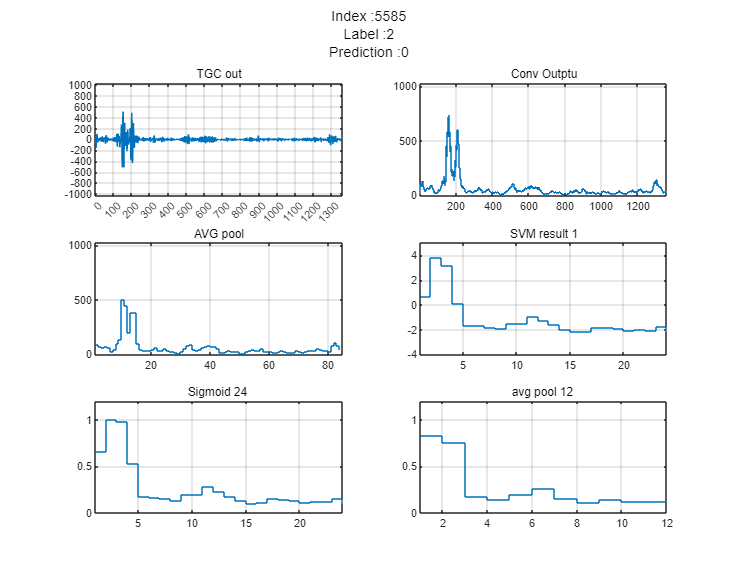

i=5585;

subplot(3,2,1)

plot(input_tgc(i,1:end-1));
title('TGC out');
xlim([0 1360])
ylim([-1024 1023])
set(gca,'Xtick',0:100:1360);
set(gca,'Ytick',-1000:200:1000);
grid on

subplot(3,2,2)

stairs(DATA.CONV(i,:))
[~,~]=title("Conv Outptu");
ylim([0 1023])
xlim([1 1360])
grid on

subplot(3,2,3)

stairs(DATA.AVG_pool(i,:))
ylim([0 1024])
xlim([1 85])
[~,~]=title("AVG pool");
grid on

subplot(3,2,4)

stairs(DATA.FIRST_SVM(i,:))
ylim([-4 5])
xlim([1 24])
[~,~]=title("SVM result 1");
grid on

subplot(3,2,5)

stairs(DATA.Sigmoid_24(i,:))
ylim([0 1.2])
xlim([1 24])
[~,~]=title("Sigmoid 24 ");
grid on

subplot(3,2,6)

stairs(DATA.AVG_pool_12(i,:))
ylim([0 1.2])
set(gcf,"Position",[100 100 900 700])
xlim([1 12])
[~,~]=title("avg pool 12 ");
grid on

sgtitle({append('Index :', num2str(i)) ; append('Label :', num2str(input_tgc(i,end))) ; append('Prediction :', num2str(Prediction(i)))},"FontSize",12)